# Smartfin filter_derived_heave Demo

The below notebook is a demo of the filter_derived_heave provided in this repo.

filter_derived_heave takes in a table with the following properties

(required) Accelerometer - this property should contain the three-axis accelerations in meters/sec/sec in the east-north-up coordinate convention.

(required) Gyroscope - this property should contain the three-axis angular velocities in rad/sec, also in the east-north-up coordinate convention.

(optional) Magnetometer - this property should contain the three-axis magnetometer readings in microteslas.

When provided the three above properties, filter_derived_heave uses [ahrsfilter](https://www.mathworks.com/help/fusion/ref/ahrsfilter-system-object.html).  If the magnetometer is missing from the table, then [imufilter](https://www.mathworks.com/help/nav/ref/imufilter-system-object.html) is used instead.  Both of these options are demonstrated below.

The dataset we choose to use for these demo starts with the VN-300 flat on the table.  It is then raised to 20cm above the table and returned to the desk.  This operation is repeated multiple times.

data_filename = './sample_data/vectornav_vertical_5_17.csv';

Below, we load the data from our sample dataset.  To support differing sampling rates, we compute the sampling rate from the dataset.  We then load the data provided by the VN-300.

% Our sample data has headers on the first line, so skip it
data = csvread(data_filename, 1);

% We'll use the time that the sample starts as each time
time = data(:, 1) * 10^(-9);
time = time - time(1);

% Using the first timestamp, calculate the sampling rate.
% With the configuration for the VectorNav, this will remain consistent.
sampling_rate = 1 / (time(2) - time(1));
target_frequency = 10;

% Downsample the time to match the downsampled data generated as part of
% the filter_derived_heave.
time_downsampled = downsample(time, int32(sampling_rate) / target_frequency);

% load the data from the dataset.
accel = data(:, 10:12);
gyro = data(:, 7:9);
mag = data(:, 19:21);

In order to use ahrsfilter with filter_derived_heave, we have to provide a table that has Accelerometer, Gyroscope, and Magnetometer data.  When all three are provided, ahrsfilter is automatically chosen.

% Load data for the ahrsfilter.  ahrsfilter requires Accelerometer,
% Gyroscope, and Magnetometer.
ahrs_sensor_data = table;
ahrs_sensor_data.Accelerometer = accel;
ahrs_sensor_data.Gyroscope = gyro;
ahrs_sensor_data.Magnetometer = mag;

% filter_derived_heave uses ahrsfilter if Magnetometer is provided.
[ahrs_acceleration, ahrs_velocity, ahrs_position] = filter_derived_heave(ahrs_sensor_data, sampling_rate, target_frequency);

Likewise, in order to use imufilter with filter_derived_heave, we only need to provide a table that has Accelerometer and Gyroscope data.  In this case, imufilter is automatically chosen.

% Load data for the imufilter. imufilter only requires Accelerometer and
% Gyroscope.
imu_sensor_data = table;
imu_sensor_data.Accelerometer = accel;
imu_sensor_data.Gyroscope = gyro;

% filter_derived_heave uses imufilter if Magnetometer is not provided.
[imu_acceleration, imu_velocity, imu_position] = filter_derived_heave(imu_sensor_data, sampling_rate, target_frequency);

Next, we will present the acceleration transformed from the sensor body to the world body.

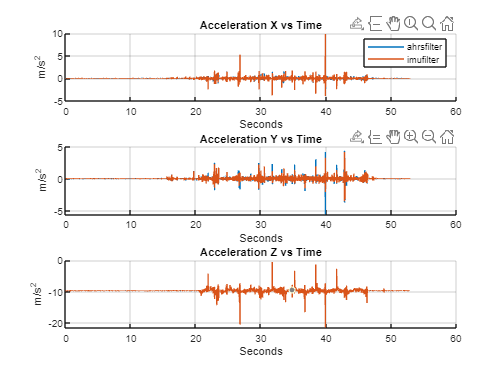

clf;

subplot(3,1,1);
hold on;
plot(time, ahrs_acceleration(:, 1));
plot(time, imu_acceleration(:, 1));
title("Acceleration X vs Time")
xlabel("Seconds")
ylabel("m/s^2")
legend("ahrsfilter", "imufilter");
hold off;
grid on;

subplot(3,1,2);
hold on;
plot(time, ahrs_acceleration(:, 2));
plot(time, imu_acceleration(:, 2));
title("Acceleration Y vs Time")
xlabel("Seconds")
ylabel("m/s^2")
hold off;
grid on;

subplot(3,1,3);
hold on;
plot(time, ahrs_acceleration(:, 3));
plot(time, imu_acceleration(:, 3));
title("Acceleration Z vs Time")
xlabel("Seconds")
ylabel("m/s^2")
hold off;
grid on;

Here, we can see each of the accelerations.  In the z-axis, we can see spikes that are associated each of the upward and downward movements, as expected.

Next, we will use the acceleration z-axis to calculate velocity and position.  To do so, we will first integrate the acceleration to velocity.  We will then integrate from velocity to position.

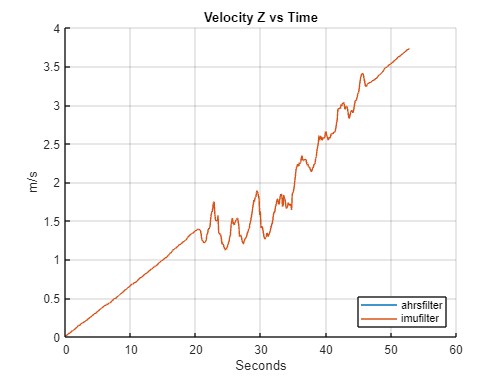

clf;
hold on;
plot(time_downsampled, ahrs_velocity);
plot(time_downsampled, imu_velocity);
ylabel("m/s");
xlabel("Seconds")
title("Velocity Z vs Time");
legend({"ahrsfilter", "imufilter"}, "Location", "southeast")
grid on;
hold off;

When reviewing the above graph, it becomes clear that both of these filters result in errors.  These errors come from the additive nature of biases within the acceleration when integrating.  Each timestamp contains the sum of each bias that comes before it.

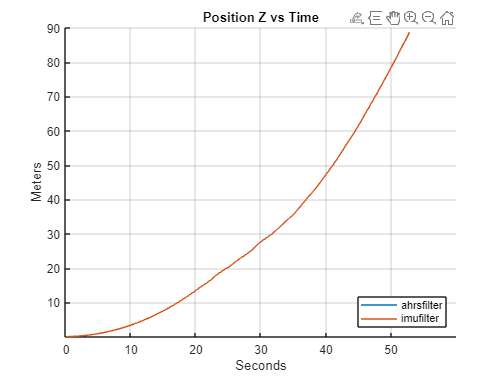

clf;
hold on;
plot(time_downsampled, ahrs_position);
plot(time_downsampled, imu_position);
ylabel("Meters");
xlabel("Seconds")
title("Position Z vs Time");
legend({"ahrsfilter", "imufilter"}, "Location", "southeast")
grid on;
hold off;

Like the velocity graph above, we see substaintial errors here.  These errors once again come from the additive nature of the errors in the velocity when integrating from velocity to position.  The errors here are exponential instead of linear.

For future work, we intend tranistion from assuming that the accelerations are deterministic and consider them as a random variable.  In order to do that, we will extend our use of Kalman filters to also estimate position and velocity.